## Assignment 1

Authors:

Kolja Westphal (455887) 

Thineth Gamage (456727)

### Task 1:

%% Functions
fc = OrbitPropagation;

%% Constants
mu   = 398600.4418;          % [km^3/s^2]
Re   = 6378.1363;            % [km]
J2   = 1.08262668e-3;        % [-]
we   = 7.2921159e-5;         % [rad/s] Earth rotation (sidereal)

%% Assignment assumptions
Omega = deg2rad(0);
omega = deg2rad(0);
nu0   = deg2rad(0);       % true anomaly at t0

1b) SSO inclination (hp=550 km, e=0.01), propagate 30 revs

year_sec = 365.2422*86400;      % s
Omega_dot_target = 2*pi/year_sec; % rad/s (sun-synchronous)

% Given orbit parameters
hp = 550;                       % km (perigee height)
e  = 0.01;
rp = Re + hp;                   % km
a  = rp/(1 - e);                % km
p  = a*(1 - e^2);
n  = sqrt(mu/a^3);              % rad/s

% SSO inclination from J2 nodal regression: dΩ/dt = -(3/2) J2 n (Re/p)^2 cos(i)
cosi = -Omega_dot_target / (1.5*J2*n*(Re/p)^2);
i    = acos(max(-1,min(1,cosi)));  % radians (clamped)

% Assignment angles
Omega = 0; omega = 0; nu0 = 0;

% Propagate 30 orbits
T  = 2*pi/n;                   % s
orbits = 30;                    
t0 = 0; tf = orbits*T;         % s 
dt = 60;

Run 1b)

This functions outputs the position [km] and velocity [km/s] vectors (R and V) propagated with the newton method for an unperturbed orbit

[t_vec, R_newton_unperturbed, V_newton_unperturbed] = fc.propagate_orbit_keplar_newton(a,e,i,Omega,omega,nu0,mu,t0,tf,dt,0,0);

1c)     

Now Plotting the Orbit. First for the plot itself a few variables like earth itself and so on...

Re = 6378.1363;            % km
we = 7.2921159e-5;         % rad/s (Earth rotation rate)
theta_g0 = 0;              % GMST at t0 (assume 0 for assignment)
t0 = t_vec(1);

Now for the plot itself:

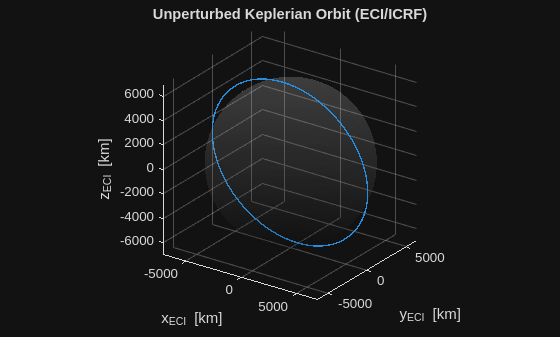

figure('Name','3D Orbit (ECI)');
plot3(R_newton_unperturbed(:,1), R_newton_unperturbed(:,2), R_newton_unperturbed(:,3), 'LineWidth', 1.0); hold on; grid on; axis equal;
% Draw a translucent Earth
[fX,fY,fZ] = sphere(80);
surf(Re*fX, Re*fY, Re*fZ, 'FaceAlpha', 0.1, 'EdgeColor', 'none'); colormap gray;
xlabel('x_{ECI} [km]'); ylabel('y_{ECI} [km]'); zlabel('z_{ECI} [km]');
title('Unperturbed Keplerian Orbit (ECI/ICRF)');
view(35,25);

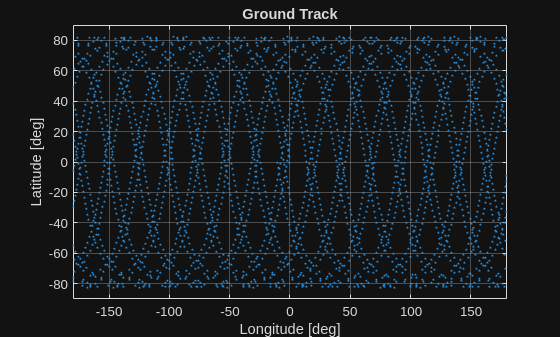

% -------- Ground Track --------
[lat_deg_newton_unperturbed, lon_deg_newton_unperturbed] = fc.convert_eci2lla(R_newton_unperturbed, t_vec, we, theta_g0);

% Wrap longitudes to [-180,180]
lon_deg_newton_unperturbed = mod(lon_deg_newton_unperturbed + 180, 360) - 180;

figure('Name','Ground Track');
plot(lon_deg_newton_unperturbed, lat_deg_newton_unperturbed, '.', 'MarkerSize', 4); grid on;
xlim([-180 180]); ylim([-90 90]);
xlabel('Longitude [deg]'); ylabel('Latitude [deg]');
title('Ground Track');

### Task 2:

This functions outputs the position [km] and velocity [km/s] vectors (R and V) propagated with the newton method for an perturbed orbit

[t_vec, R_newton_perturbed, V_newton_perturbed] = fc.propagate_orbit_keplar_newton(a,e,i,Omega,omega,nu0,mu,t0,tf,dt,Re,J2);

Now the orbital plots

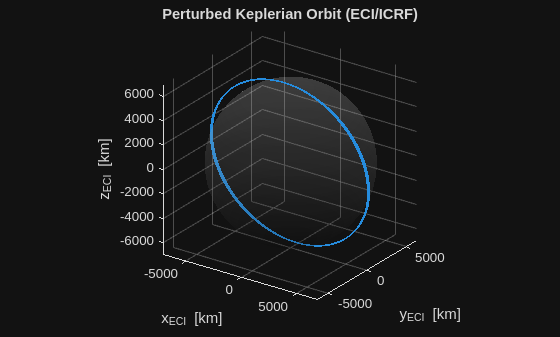

figure('Name','3D Orbit (ECI)');
plot3(R_newton_perturbed(:,1), R_newton_perturbed(:,2), R_newton_perturbed(:,3), 'LineWidth', 1.0); hold on; grid on; axis equal;
% Draw a translucent Earth
[fX,fY,fZ] = sphere(80);
surf(Re*fX, Re*fY, Re*fZ, 'FaceAlpha', 0.1, 'EdgeColor', 'none'); colormap gray;
xlabel('x_{ECI} [km]'); ylabel('y_{ECI} [km]'); zlabel('z_{ECI} [km]');
title('Perturbed Keplerian Orbit (ECI/ICRF)');
view(35,25);

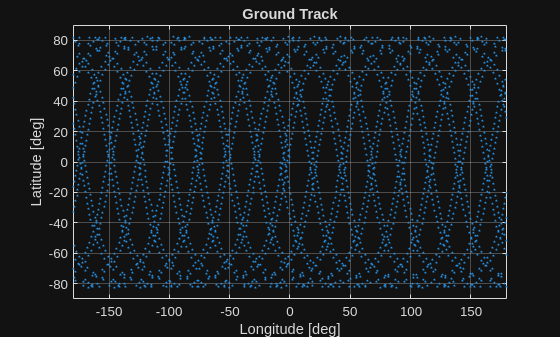

% -------- Ground Track --------
[lat_deg_newton_perturbed, lon_deg_newton_perturbed] = fc.convert_eci2lla(R_newton_perturbed, t_vec, we, theta_g0);

% Wrap longitudes to [-180,180]
lon_deg_newton_perturbed = mod(lon_deg_newton_perturbed + 180, 360) - 180;

figure('Name','Ground Track');
plot(lon_deg_newton_perturbed, lat_deg_newton_perturbed, '.', 'MarkerSize', 4); grid on;
xlim([-180 180]); ylim([-90 90]);
xlabel('Longitude [deg]'); ylabel('Latitude [deg]');
title('Ground Track');

### Task 3:

3b) Propagating the orbit using the Orbit EoMs

First we convert from keplar to cartesian coordinates

% Convert keplar elements to position and velocity vectors
[rr0, vv0] = fc.convert_kep2car(a, e, i, Omega, omega, nu0, mu);

This functions outputs the position [km] and velocity [km/s] vectors (R and V) propagated with the RK4  method for an unperturbed orbit

%Propagate unperturbed orbit EoM
[t_vec, R_rk4_unpertubred, V_rk4_unperturbed] = fc.propagate_orbit_EoM_rk4(rr0, vv0, t0, tf, dt, mu, 0, 0);

3c) Now with J2 for a perturbed orbit

%Propagate perturbed orbit EoM
[t_vec, R_rk4_perturbed, V_rk4_perturbed] = fc.propagate_orbit_EoM_rk4(rr0, vv0, t0, tf, dt, mu, Re, J2);

### Task 4:

4a)

Now we plot the difference in the x, y and z coordinates between an unperturbed and perturbed orbit,

that was propagated with the newton method. Due to the assumption, that the J2 Pertubation does not change the inclination

of the orbit, the difference in the z component in 0. The difference in x and y continuously increases as over time as the 

argument of the perigee and the position of the ascending node is influence by J2.

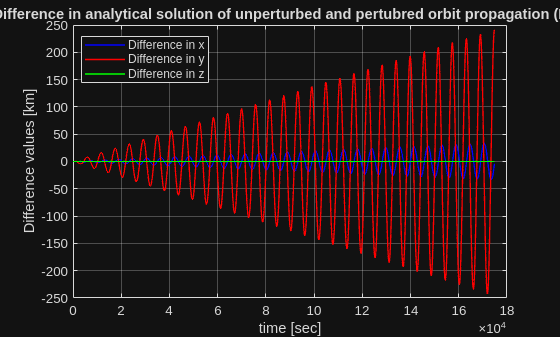

% Plot comparison of newton method between the unperturbed and perturbed orbit
comparison_analytical_perturbed_unperturbed = R_newton_perturbed - R_newton_unperturbed;

figure('Name','Difference in analytical solution of unperturbed and perturbed orbit');
plot(t_vec, comparison_analytical_perturbed_unperturbed(:,1), 'b', 'LineWidth', 1.0); hold on; grid on;
plot(t_vec, comparison_analytical_perturbed_unperturbed(:,2), 'r', 'LineWidth', 1.0); 
plot(t_vec, comparison_analytical_perturbed_unperturbed(:,3), 'g', 'LineWidth', 1.0); 
legend('Difference in x','Difference in y', 'Difference in z','Location','best');
xlabel('time [sec]'); ylabel('Difference values [km]'); hold off;
title('Difference in analytical solution of unperturbed and pertubred orbit propagation (ECI)')

4b)

The following plot shows the difference in the x,y and z component of the position vectors between a perturbed orbit propagated

with the newton method and the RK4 method. For every component, we see a continuous increase in the difference as the error

that is caused by solving the EoM numerically increases over time.

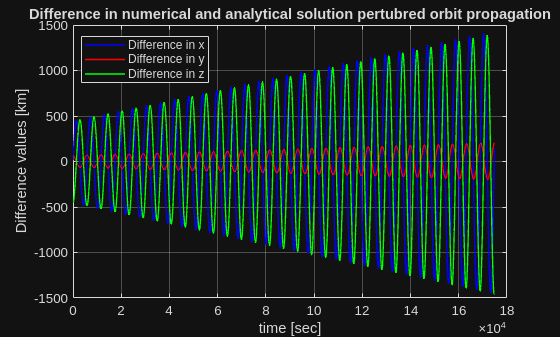

% Plot comparison of perturbed orbit between newton and rk4 method
comparison_analytical_rk4 = R_newton_perturbed - R_rk4_perturbed;

figure('Name','Difference in numerical and analytical solution pertubred orbit propagation');
plot(t_vec, comparison_analytical_rk4(:,1), 'b', 'LineWidth', 1.0); hold on; grid on;
plot(t_vec, comparison_analytical_rk4(:,2), 'r', 'LineWidth', 1.0); 
plot(t_vec, comparison_analytical_rk4(:,3), 'g', 'LineWidth', 1.0); 
legend('Difference in x','Difference in y', 'Difference in z','Location','best');
xlabel('time [sec]'); ylabel('Difference values [km]'); hold off;
title('Difference in numerical and analytical solution pertubred orbit propagation')